# **Control On/Off - Bergman Modificado.**

**Elaborado por: **Manuela María Muriel Tobar, David Andrés Ojeda Guzmán

**Universidad de Nariño**

En este script se implementa un controlador On/Off para el modelo modificado de Bergman.

Se simula un escenario de 24 horas con resolución de 1 minuto, 3 ingestas de comida.

El controlador se enciende (On) cuando se supera el umbral de 180 mg/dL y se apaga por debajo de el (Off), se inyecta una cantidad fija de insulina que trata de mantener la referencia. se implementa ademas histeresis en el controlador para evitar el switcheo rapido. Finalmente se evaluan metricas clinicas (TIR, tiempo en hiperglucemia, tiempo en hipoglucemia, coeficiente de variación) y ademas se evaluan metricas clasicas de control (IAE, ISE, ITAE)

close all; clear variables; clc;

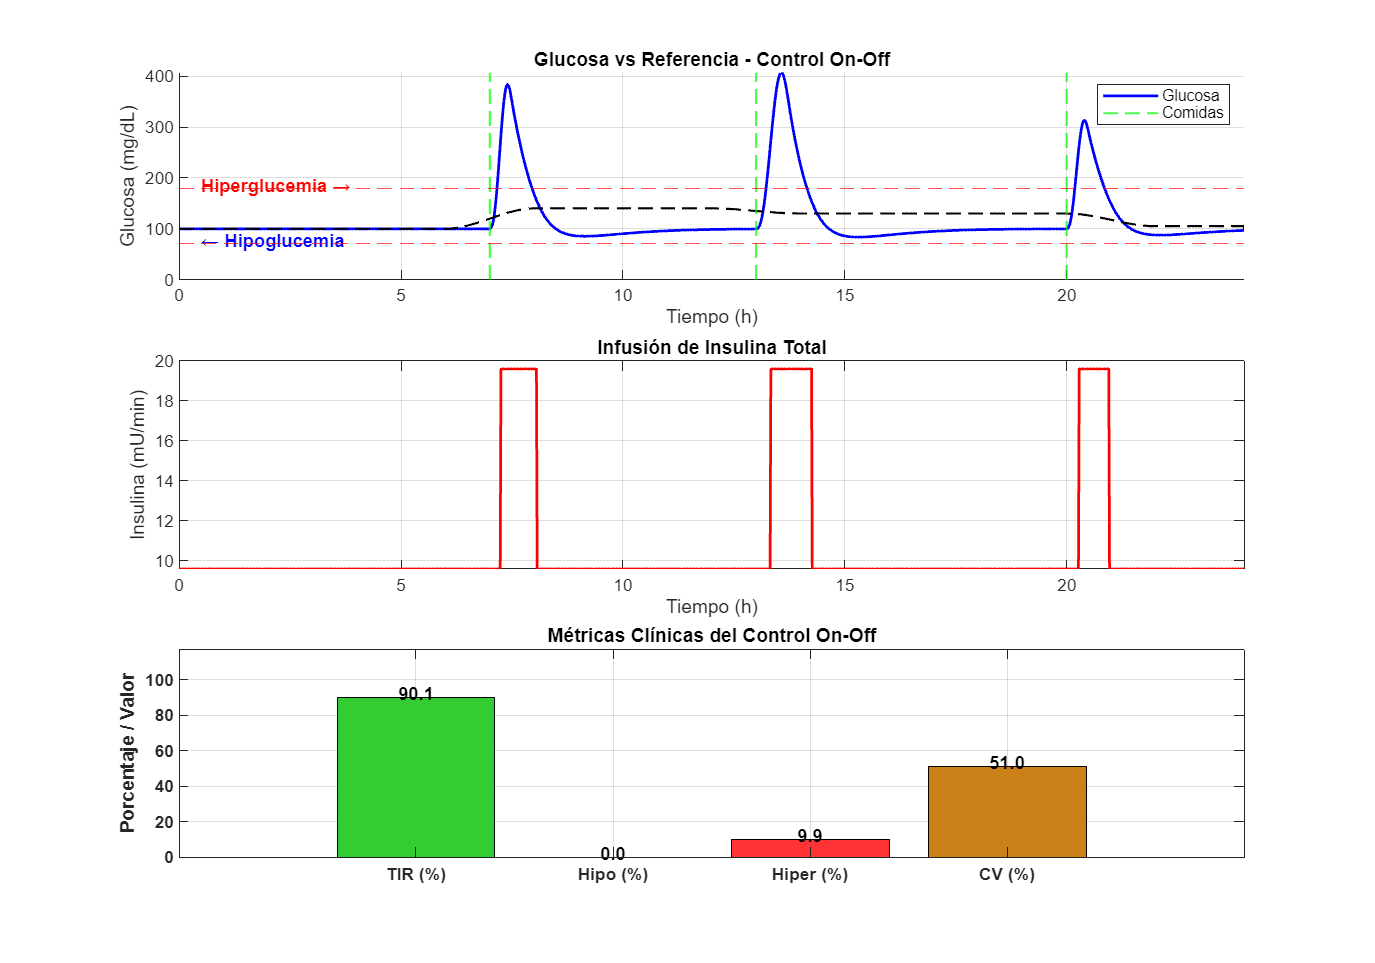

%% PARÁMETROS DEL MODELO
p1 = 0.03; p2 = 0.02; p3 = 4.5e-5; p4 = 0.08;
Gb = 100; Ib = 10; VI = 12;

%% CONDICIONES INICIALES
G0 = 100; X0 = 0; I0 = Ib; Dt0 = 0; Gsc0 = G0;
y0 = [G0; X0; I0; Dt0; Gsc0];

%% TIEMPO DE SIMULACIÓN
t_sim = 0:1:24*60; % en minutos
dt = 1; % paso fijo

%% PERFIL DE COMIDAS
meal_times = [7*60, 13*60, 20*60];
meal_amounts = [20, 25, 15];
meal_durations = [30, 45, 30];

D = @(t) definir_D_multi_mejorado(t, ...
    [meal_amounts(1), meal_times(1), meal_durations(1)], ...
    [meal_amounts(2), meal_times(2), meal_durations(2)], ...
    [meal_amounts(3), meal_times(3), meal_durations(3)]);

%% REFERENCIA DE GLUCOSA
Gref_fun = @(t) smooth_glucose_reference(t);

%% CONTROLADOR ON-OFF
U_min = p4 * VI * Ib;
U_max = U_min + 10;
hysteresis = 5;
last_mode = 'off';

%% PREALOCACIÓN
Y = zeros(length(t_sim), length(y0));
U = zeros(size(t_sim));
G_ref_vec = zeros(size(t_sim));

IAE = 0; ISE = 0; ITAE = 0; % Inicializar índices

%% SIMULACIÓN
y = y0;
for k = 1:length(t_sim)
    t = t_sim(k);
    G = y(1); Gsc = y(5);
    G_ref = Gref_fun(t);
    G_ref_vec(k) = G_ref;

    % Lógica del controlador On-Off con histéresis
    if Gsc < 70
        U_k = U_min * 0.5;
        last_mode = 'off';
    elseif Gsc <= 180
        U_k = U_min;
        last_mode = 'off';
    else
        switch last_mode
            case 'off'
                if Gsc > 180 + hysteresis
                    U_k = U_max;
                    last_mode = 'on';
                else
                    U_k = U_min;
                end
            case 'on'
                if Gsc < 180 - hysteresis
                    U_k = U_min;
                    last_mode = 'off';
                else
                    U_k = U_max;
                end
        end
    end

    U(k) = U_k;
    [~, y_sol] = ode45(@(t_, y_) modelo_no_lineal(t_, y_, p1, p2, p3, p4, Gb, Ib, VI, U_k, D), [t t+dt], y);
    y = y_sol(end,:)';
    Y(k,:) = y;

    % Cálculo incremental de índices de desempeño
    e_k = G_ref - G;
    IAE = IAE + abs(e_k) * dt;
    ISE = ISE + (e_k^2) * dt;
    ITAE = ITAE + t * abs(e_k) * dt;
end

%% MÉTRICAS CLÍNICAS
glucosa = Y(:,1);
TIR = sum(glucosa >= 70 & glucosa <= 180) / length(glucosa) * 100;
hipo = sum(glucosa < 70) / length(glucosa) * 100;
hiper = sum(glucosa > 180) / length(glucosa) * 100;
media_G = mean(glucosa);
CV = std(glucosa) / media_G * 100;

%% GRÁFICAS
figure('Color','w', 'Position', [100 100 1000 700]);

% === Subplot 1: Glucosa ===
subplot(3,1,1); hold on;
h_glucose = plot(t_sim/60, Y(:,1), 'b', 'LineWidth', 1.5);
for j = 1:length(meal_times)
    h_meal(j) = xline(meal_times(j)/60, '--g', 'LineWidth', 1.2, 'Alpha', 0.7);
end
plot(t_sim/60, G_ref_vec, 'k--', 'LineWidth', 1.2);
yline(70, 'r--'); yline(180, 'r--');
legend([h_glucose, h_meal(1)], 'Glucosa', 'Comidas', 'Location', 'northeast');
title('Glucosa vs Referencia - Control On-Off');
ylabel('Glucosa (mg/dL)'); xlabel('Tiempo (h)'); grid on; xlim([0 24]);
text(0.5, 75, '← Hipoglucemia', 'Color', 'blue', 'FontWeight','bold');
text(0.5, 185, 'Hiperglucemia →', 'Color', 'red', 'FontWeight','bold', 'HorizontalAlignment','left');

% === Subplot 2: Insulina ===
subplot(3,1,2);
plot(t_sim/60, U, 'r', 'LineWidth', 1.5);
title('Infusión de Insulina Total');
ylabel('Insulina (mU/min)'); xlabel('Tiempo (h)'); grid on; xlim([0 24]);

% === Subplot 3: Métricas Clínicas ===
subplot(3,1,3);
metrics = [TIR, hipo, hiper, CV];
names = {'TIR (%)','Hipo (%)','Hiper (%)','CV (%)'};
colors = [0.2 0.8 0.2; 0.2 0.2 1; 1 0.2 0.2; 0.8 0.5 0.1];
b = bar(metrics, 'FaceColor','flat');
for i = 1:4
    b.CData(i,:) = colors(i,:);
    text(i, metrics(i) + 2, sprintf('%.1f', metrics(i)), ...
        'HorizontalAlignment','center','FontWeight','bold');
end
ylim([0 max(metrics)*1.3]);
title('Métricas Clínicas del Control On-Off');
ylabel('Porcentaje / Valor');
set(gca, 'XTickLabel', names, 'FontWeight','bold');
grid on;


%% IMPRESIÓN FINAL DE ÍNDICES DE DESEMPEÑO
fprintf('\n=== ÍNDICES DE DESEMPEÑO ===\n');


=== ÍNDICES DE DESEMPEÑO ===


fprintf('IAE  (Integral of Absolute Error):     %.2f\n', IAE);

IAE  (Integral of Absolute Error):     50793.34


fprintf('ISE  (Integral of Squared Error):      %.2f\n', ISE);

ISE  (Integral of Squared Error):      5013140.37


fprintf('ITAE (Integral of Time-weighted Abs):  %.2f\n', ITAE);

ITAE (Integral of Time-weighted Abs):  42246324.32



%% FUNCIONES AUXILIARES
function D_output = definir_D_multi_mejorado(t, varargin)
    D_output = 0;
    for i = 1:size(varargin,2)
        carga_g = varargin{i}(1);
        t_ini = varargin{i}(2);
        dur = varargin{i}(3);

        % Aproximación: 1 g de CHO equivale a 20 mg/dL en plasma
        FACTOR_MG_POR_G_CHO_EN_PLASMA = 1000 / 50;
        carga_mg_equivalente = carga_g * FACTOR_MG_POR_G_CHO_EN_PLASMA;

        if t >= t_ini && t <= t_ini + dur
            tau_abs = (t - t_ini) / dur;
            profile_shape = tau_abs.^2 .* (1 - tau_abs).^2;
            normalizacion_factor_profile = 1/30;  % Ajuste empírico

            D_output = D_output + ...
                (carga_mg_equivalente / dur) * (profile_shape / normalizacion_factor_profile);
        end
    end
end


function ref_val = smooth_glucose_reference(t_min)
    h = mod(t_min/60, 24);
    if h < 6
        ref_val = 100;
    elseif h < 8
        alpha = (h - 6)/2;
        ref_val = 100 + (140 - 100)*(3*alpha^2 - 2*alpha^3);
    elseif h < 12
        ref_val = 140;
    elseif h < 14
        alpha = (h - 12)/2;
        ref_val = 140 + (130 - 140)*(3*alpha^2 - 2*alpha^3);
    elseif h < 20
        ref_val = 130;
    elseif h < 22
        alpha = (h - 20)/2;
        ref_val = 130 + (105 - 130)*(3*alpha^2 - 2*alpha^3);
    else
        ref_val = 105;
    end
end

function dydt = modelo_no_lineal(t, y, p1, p2, p3, p4, Gb, Ib, VI, U, D_func)
    G = y(1); X = y(2); I = y(3); Dt = y(4); Gsc = y(5);
    D_val = D_func(t);
    dGdt = -(p1 + X)*G + p1*Gb + Dt;
    dXdt = -p2*X + p3*(I - Ib);
    dIdt = -p4*I + U/VI;
    dDdt = -2*Dt + 2*D_val;
    dGscdt = (1/5)*(G - Gsc);
    dydt = [dGdt; dXdt; dIdt; dDdt; dGscdt];
end
